# Assignment 02

Lauren Morlock

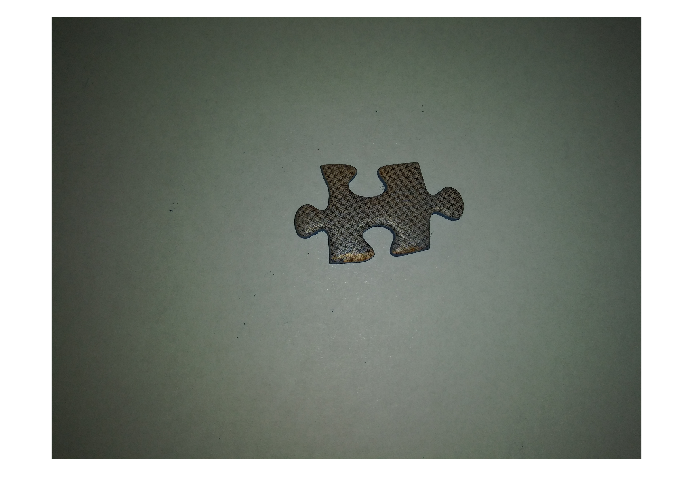

% main code sequence
% reads images, calls masking function, displays mask

im = imread("piece 1.jpg");
imshow(im)

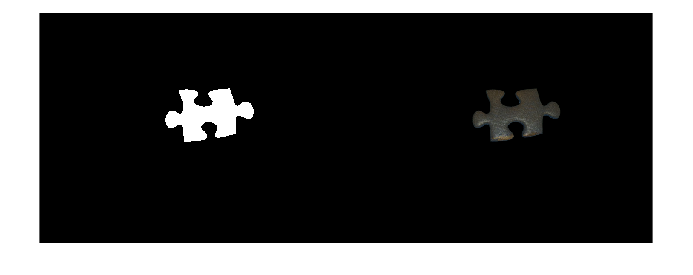


[imBW, imMask] = segmentImage(im);

montage({imBW, imMask})

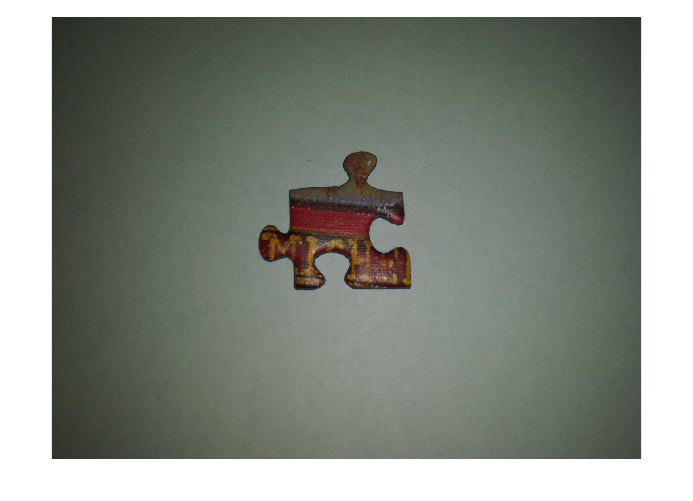


im = imread("piece 2.jpg");
imshow(im)

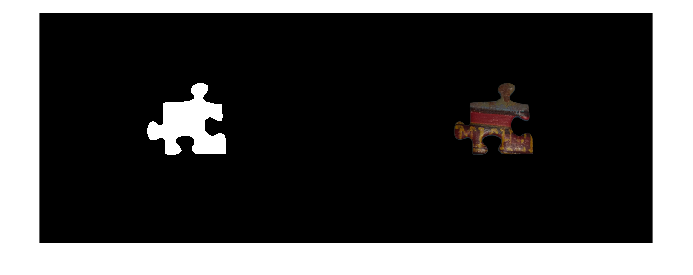


[imBW, imMask] = segmentImage(im);

montage({imBW, imMask})

function [BW,maskedImage] = segmentImage(RGB)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(RGB) segments image RGB using
%  auto-generated code from the Image Segmenter app. The final segmentation
%  is returned in BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 11-Feb-2023
%----------------------------------------------------


% Convert RGB image into L*a*b* color space.
X = rgb2lab(RGB);

% Graph cut
foregroundInd = [6456650 7149300 ];
backgroundInd = [2717830 3213921 5513493 6256085 6752170 7348080 7928379 8093739 8174859 8686539 8770779 8886219 9085893 9232523 9347963 9513318 9959467 10143536 10324486 10655185 10886059 10901659 10951579 10970299 11001499 ];
L = superpixels(X,64996,'IsInputLab',true);

% Convert L*a*b* range to [0 1]
scaledX = prepLab(X);
BW = lazysnapping(scaledX,L,foregroundInd,backgroundInd);

% Active contour
iterations = 100;
BW = activecontour(X, BW, iterations, 'Chan-Vese');

% Open mask with rectangle
dimensions = [11 3];
se = strel('rectangle', dimensions);
BW = imopen(BW, se);

% Close mask with disk
radius = 10;
decomposition = 8;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Create masked image.
maskedImage = RGB;
maskedImage(repmat(~BW,[1 1 3])) = 0;
end

function out = prepLab(in)

% Convert L*a*b* image to range [0,1]
out = in;
out(:,:,1) = in(:,:,1) / 100;  % L range is [0 100].
out(:,:,2) = (in(:,:,2) + 86.1827) / 184.4170;  % a* range is [-86.1827,98.2343].
out(:,:,3) = (in(:,:,3) + 107.8602) / 202.3382;  % b* range is [-107.8602,94.4780].

end
